# Advanced Computation For Energy Assignments

### **Name:** Abisoye Akinloye Samson

### **Track:** Energy Engineering

### **Academic Year:** 2025

## Assignment 1

[https://www.wunderground.com/dashboard/pws/IVANDU8/table/2024-08-25/2024-08-25/monthly](https://www.wunderground.com/dashboard/pws/IVANDU8/table/2024-08-25/2024-08-25/monthly)

Take the csv file, read it with Matlab, extract the columns: 

- Average Temperature, 

- Average Humidity, 

- Average  Wind speed  

Display the curves over the days of the month.

%% Program to read, manipulate, and plot weather data
clc; clear; close all;

%% Load the Data
data = readtable("weather.csv", "VariableNamingRule","preserve", "ReadVariableNames",true);
% display 5 rows of the data
data(2:5,:);

% select needed columns from the data (temperature, humidity, speed)
date = data(2:end,"Var1"); % date -> the first column
temp = data(2:end,2:4);    % temperature 
humdity = data(2:end,8:10);% humidity
speed = data(2:end,11:13); % speed (mph)

% Date Column
% rename the header variable
date = renamevars(date, "Var1","Date");
% view the first 5 rows of the data
date(1:5,:)

ans = 5×1 table
       Date   
    __________

    08/07/2024
    08/08/2024
    08/09/2024
    08/10/2024
    08/11/2024


% temperature
temp = renamevars(temp,["Temperature","Dew Point","Humidity"],["High_Temp","Avg_Temp","Low_Temp"]);
temp(1:5,:)

ans = 5×3 table
     High_Temp      Avg_Temp       Low_Temp  
    ___________    ___________    ___________

    {'81.0 °F'}    {'73.5 °F'}    {'63.7 °F'}
    {'79.2 °F'}    {'68.6 °F'}    {'61.2 °F'}
    {'84.4 °F'}    {'72.3 °F'}    {'62.6 °F'}
    {'85.3 °F'}    {'73.8 °F'}    {'63.7 °F'}
    {'88.3 °F'}    {'75.8 °F'}    {'59.7 °F'}


% humidity
humdity = renamevars(humdity,["Var8","Var9","Var10"],["High_Hum","Avg_Hum","Low_Hum"]);
humdity(1:5,:)

ans = 5×3 table
    High_Hum    Avg_Hum     Low_Hum 
    ________    ________    ________

    {'88 %'}    {'72 %'}    {'59 %'}
    {'92 %'}    {'67 %'}    {'45 %'}
    {'80 %'}    {'64 %'}    {'45 %'}
    {'92 %'}    {'71 %'}    {'48 %'}
    {'88 %'}    {'62 %'}    {'47 %'}


% speed
% rename speed header variable
speed = renamevars(speed,["Var11","Var12","Var13"],["High_Speed","Avg_Speed","Low_Speed"]);
speed(1:5,:)

ans = 5×3 table
     High_Speed      Avg_Speed      Low_Speed 
    ____________    ___________    ___________

    {'11.2 mph'}    {'2.4 mph'}    {'0.0 mph'}
    {'6.9 mph' }    {'1.0 mph'}    {'0.0 mph'}
    {'13.7 mph'}    {'2.8 mph'}    {'0.0 mph'}
    {'7.6 mph' }    {'1.6 mph'}    {'0.0 mph'}
    {'9.2 mph' }    {'2.3 mph'}    {'0.0 mph'}


#### **Key Takeaways:**

- **Renaming table header variable name. Source: **[https://www.mathworks.com/help/matlab/ref/table.renamevars.html](https://www.mathworks.com/help/matlab/ref/table.renamevars.html)

- **Reading table and preserving variable naming. Source: **[https://www.academia.edu/96835174/DATA_PRE_PROCESSING_IN_MATLAB](https://www.academia.edu/96835174/DATA_PRE_PROCESSING_IN_MATLAB)

**Data Manipulation**

- The CSV file downloaded is messy (i.e containing alphanumeric) including charater, degrees, and percentage symbol. 

- However, since numeric datapoint (quantitative data) are need for the plotting.

- Characters and symbols should be removed. Hence, Instead of doing it manually using Excel,

- Matlab has some in-built function for data cleaning and manipulation.

% Data Manipulation
% remove degree F from the temperature 
avg_temp_ = temp(:,2).Variables;
A = string(avg_temp_); % change cell to string array
% data casting string -> number
avg_temp = str2double(strrep(A, ' °F', ''))

avg_temp =    73.5000
   68.6000
   72.3000
   73.8000
   75.8000
   80.8000
   83.1000
   68.2000
   71.4000
   72.6000


% remove percentage from humidity 
avg_humdity_ =  humdity(:,2).Variables;
B = string(avg_humdity_); % chnage cell to string array
avg_humidity = str2double(strrep(B, '%', ''))

avg_humidity =     72
    67
    64
    71
    62
    62
    59
    90
    73
    62


% remove mph from speed
avg_speed_ =  speed(:,2).Variables;
C = string(avg_speed_); % chnage cell to string array
avg_speed = str2double(strrep(C, ' mph', ''))

avg_speed =     2.4000
    1.0000
    2.8000
    1.6000
    2.3000
    1.8000
    2.0000
    2.5000
    0.8000
    2.1000


% date already in datetime datatype
date = date.Variables;

#### Key Takeaways:

- **How to change string datatype to double. (Source:** [https://www.mathworks.com/help/matlab/ref/str2double.html](https://www.mathworks.com/help/matlab/ref/str2double.html)**)**

- **How to replace occurrence of a string to another string. (Source:** [https://www.mathworks.com/help/matlab/ref/strrep.html](https://www.mathworks.com/help/matlab/ref/strrep.html)**)**

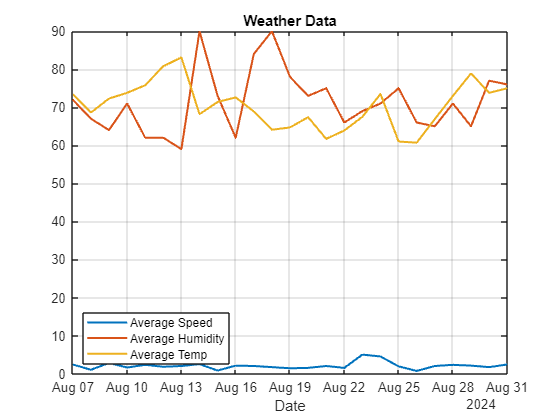

% plot the graph
figure(1)
plot(date,avg_speed,date,avg_humidity,date,avg_temp,'LineWidth', 1.5)
xlabel("Date")
legend(["Average Speed","Average Humidity", "Average Temp"],"Location","southwest")
title("Weather Data")
grid on

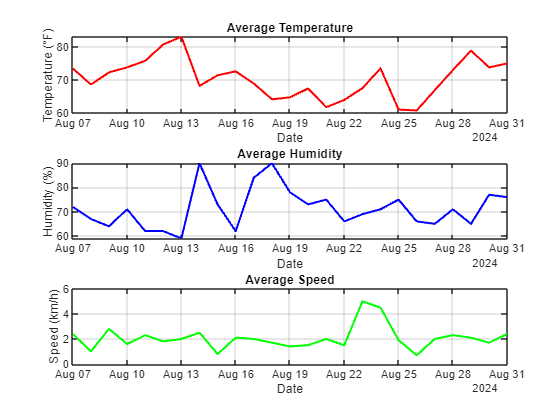

%% Using Subplot
figure(2)
% Subplot 1: Average Temperature
subplot(3,1,1);       % 3 rows, 1 column, 1st subplot
plot(date, avg_temp, '-r', 'LineWidth', 1.5);
title('Average Temperature');
xlabel('Date');
ylabel('Temperature (°F)');
grid on;

% Subplot 2: Average Humidity
subplot(3,1,2);       % 3 rows, 1 column, 2nd subplot
plot(date, avg_humidity, '-b', 'LineWidth', 1.5);
title('Average Humidity');
xlabel('Date');
ylabel('Humidity (%)');
grid on;

% Subplot 3: Average Speed
subplot(3,1,3);       % 3 rows, 1 column, 3rd subplot
plot(date, avg_speed, '-g', 'LineWidth', 1.5);
title('Average Speed');
xlabel('Date');
ylabel('Speed (km/h)');
grid on;

#### M Script Code

## Assignment 2

Implement the algorithms of Fixed-point theorem and Newton-Raphson to solve the same equation 


$$f\left(x\right)=x-\cos \left(x\right)$$


Record the values $x_k$ and $f\left(x_k \right)$ for both algorithm in arrays as explained in previous Unit  Plot, on the same figure.

#### **Fixed Point Method**

% Numerical Integration Using Fixed-Point Iteration and Newton-Raphson Method
% f(x) = x - cos(x)

clear; clc; close all;

%% Variables
iter_fp = 0; iter_nr = 0;             % iteration counter for fixed-point and Newton-Raphson
iterlim_fp = 100; iterlim_nr = 100;   % maximum number of iterations for fixed-point and Newton-Raphson
elim_fp = 1e-6; elim_nr = 1e-6;       % error tolerance for fixed-point and Newton-Raphson
x0_fp = 0; x0_nr = 0;                 % initial guess for fixed-point and Newton-Raphson
x_fp = x0_fp; x_nr = x0_nr;           % current approximation
e_fp = 1e20; e_nr = 1e20;             % initialize error to a large number

%% Fixed-point iteration loop
fprintf('Resolution by Fixed-point theorem\n');

Resolution by Fixed-point theorem


pt_xt = zeros(1, iter_fp);            % x initialized as empty array
pt_fxt = zeros(1, iter_fp);           % f(x) initialized as empty array

while (e_fp > elim_fp) && (iter_fp < iterlim_fp)
    % fixed point method: x = g(x) = cos(x)
    xnew = cos(x_fp);                 % g_function(x) = cos(x)
    e_fp = abs(xnew - x_fp);             % compute absolute error
    x_fp = xnew;                      % update the approximation
    iter_fp = iter_fp + 1;            % increment the iteration counter

    pt_xt(iter_fp)= x_fp;             % store the x value
    pt_fxt(iter_fp) = x_fp - cos(x_fp);

    fprintf('iter %d: x = %.8f, e = %.8e\n', iter_fp, x_fp, e_fp);
end

iter 1: x = 1.00000000, e = 1.00000000e+00
iter 2: x = 0.54030231, e = 4.59697694e-01
iter 3: x = 0.85755322, e = 3.17250910e-01
iter 4: x = 0.65428979, e = 2.03263425e-01
iter 5: x = 0.79348036, e = 1.39190568e-01
iter 6: x = 0.70136877, e = 9.21115851e-02
iter 7: x = 0.76395968, e = 6.25909093e-02
iter 8: x = 0.72210243, e = 4.18572579e-02
iter 9: x = 0.75041776, e = 2.83153367e-02
iter 10: x = 0.73140404, e = 1.90137193e-02
iter 11: x = 0.74423735, e = 1.28333125e-02
iter 12: x = 0.73560474, e = 8.63261446e-03
iter 13: x = 0.74142509, e = 5.82034617e-03
iter 14: x = 0.73750689, e = 3.91819610e-03
iter 15: x = 0.74014734, e = 2.64044505e-03
iter 16: x = 0.73836920, e = 1.77813145e-03
iter 17: x = 0.73956720, e = 1.19799809e-03
iter 18: x = 0.73876032, e = 8.06882338e-04
iter 19: x = 0.73930389, e = 5.43572523e-04
iter 20: x = 0.73893776, e = 3.66135682e-04
iter 21: x = 0.73918440, e = 2.46643056e-04
iter 22: x = 0.73901826, e = 1.66137344e-04
iter 23: x = 0.73913018, e = 1.11914102e-

fprintf('The fixed point is approximately x = %.8f\n', x_fp);

The fixed point is approximately x = 0.73908553


#### **Newton Raphson Method**


%% Newton Raphson iteration loop

fprintf('\nResolution by Netwon Raphson Method\n');


Resolution by Netwon Raphson Method


nr_xt = zeros(1, iter_nr);  nr_fxt = zeros(1, iter_nr);    % x and f(x) initialized as empty array

while ((e_nr > elim_nr) && (iter_nr < iterlim_nr))
    f = x_nr - cos(x_nr);            % f(x) = x - cos(x)
    df = 1 + sin(x_nr);              % f'(x) = 1 + sin(x) differentiating f(x)
    if df ~= 0
        xnew = x_nr - (f/df);        % Newton-Raphson formula
    else
        fprintf('df = 0, end of iterations\n');
        break
    end

    e_nr = abs(xnew - x_nr);
    x_nr = xnew;
    iter_nr = iter_nr + 1;

    nr_xt(iter_nr) = x_nr;
    nr_fxt(iter_nr) = f;

    fprintf('iter %d: x = %.6f, e = %.5e\n', iter_nr, x_nr, e_nr);
end

iter 1: x = 1.000000, e = 1.00000e+00
iter 2: x = 0.750364, e = 2.49636e-01
iter 3: x = 0.739113, e = 1.12510e-02
iter 4: x = 0.739085, e = 2.77575e-05
iter 5: x = 0.739085, e = 1.70123e-10



%% Plot the graphs
plot(pt_xt, pt_fxt, '-r')
hold;

Current plot held


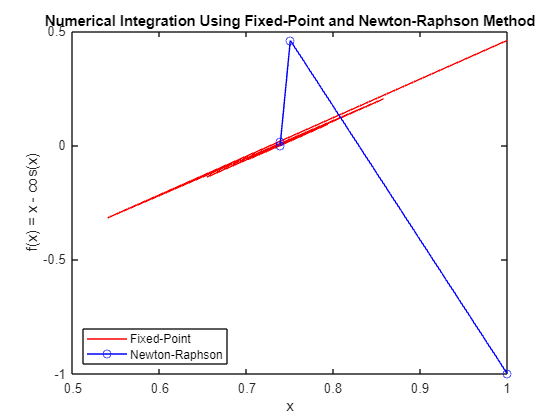

plot(nr_xt, nr_fxt, 'o-b')
ylabel('f(x) = x - cos(x)')
xlabel('x')
legend('Fixed-Point', 'Newton-Raphson','Location','southwest')
title('Numerical Integration Using Fixed-Point and Newton-Raphson Method')

#### **M Script Code**

## Assignment 3

- Build a battery emulator with its BMS

- 1s is 10 min (accelerated time) 

- The model should include charging, discharging process, State Of Charge (SOC)  

- Simulation using accelerated time in a loop

#### **Battery Usage Scenarios**

The simulation covers 24 hours with the following usage scenarios of my phone (Samsung Z Fold 5):

- **0 - 9am:** The phone was idle and the discharging rate was very low. **(**$\left.0\le \textrm{time}\;\left(\textrm{hrs}\right)<9\right)$

- **9 - 10:30am:** The phone was on standby mode as some background apps were running.$\left(9\le \textrm{time}\;\left(\textrm{hrs}\right)<10:30\right)$

- **10:30 - 10:45am:** Tea break, Login to the social media $\left(10:30\le \textrm{time}\;\left(\textrm{hrs}\right)<10:45\right)$

- **10:45 - 12pm**: The phone was in idle mode as running background was disable to concentrate in class.$\left(10:45\le \textrm{time}\;\left(\textrm{hrs}\right)<12\right)$

- **12 - 1:30pm:** Lunch Break; surfed internet, chatted on social media, and play games.$\left(12\le \textrm{time}\;\left(\textrm{hrs}\right)<13:30\right)$

- **1:30 - 3pm:** The phone was on standby mode $\left(13:30\le \textrm{time}\;\left(\textrm{hrs}\right)<15\right)$

- **3 - 3:15pm:** Short break $\left(15\le \textrm{time}\;\left(\textrm{hrs}\right)<15:15\right)$

- **3:15 - 4pm:** The phone was on standby mode.$\left(15:15\le \textrm{time}\;\left(\textrm{hrs}\right)<16\right)$

- **4 - 5pm:** Bus station; watching YouTube videos to reinforce topics taught in class.$\left(16\le \textrm{time}\;\left(\textrm{hrs}\right)<17\right)$

- **5 - 6:30pm:** Charging Mode when I got to cite. $\left(17\le \textrm{time}\;\left(\textrm{hrs}\right)<18:30\right)$

- **6:30 - 10pm**: Reading and Studying with my mobile phone $\left(18:30\le \textrm{time}\;\left(\textrm{hrs}\right)<22\right)$

- **10 - 11:30pm:** Bed time and charging $\left(22\le \textrm{time}\;\left(\textrm{hrs}\right)<23:30\right)$

- **11:30pm - 12am:** Phone on Idle mode $\left(23:30\le \textrm{time}\;\left(\textrm{hrs}\right)<00\right)$

% Battery SOC Estimation: Discharging, Charging, and Idle Scenario
clc; clear; close all;

%% Simulation parameters
tf = 24; % Total simulation time in hours
dt = 1/10; % Accelerated time step
Ntf = floor(tf/dt); % Number of simulation steps
t = 0; % Initial time in hour
fprintf("Simulation parameter initialized\n")

Simulation parameter initialized


%% Battery parameters
Qn = 5; % Battery capacity in Ah
soc = 1; % Initial SoC (100%)
i_dl = 0.015; % Idle current consumption in A
i = 0; % Initial current consumption in A
fprintf("Battery parameter initialized\nBattery Capacity = %d \nInitial State of Charge = %d%%",Qn,soc*100)

Battery parameter initialized
Battery Capacity = 5 
Initial State of Charge = 100%

%% Initialization
tt = zeros(1,Ntf); % Time vector 
soc_t = zeros(1,Ntf); % SoC vector
i_c = zeros(1,Ntf); % Current charging vector
i_d = zeros(1,Ntf); % Current discharging vector
tk = 1; % Indexing array
fprintf("Initializing array needed for plotting graph")

Initializing array needed for plotting graph

%% Numerical integration (Euler) using a while loop
while (t < tf)
    if t <= 9 
        i = i_dl; % Idle scenario (0 - 9am)
        i_d(tk) = i;
    elseif t > 9 && t <= 10.5
        % i = (remainingSoc - desiredSoc) * Qn/dt 
        % dt -> t2 - t1 (analytically); 
        % dt = 0.1 (accelerated time for t iteration)
        i = 0.1; % Standby scenario (9 - 10:30am)
        i_d(tk) = 1;
    elseif t > 10.5 && t <= 10.75
        i = 0.5; % Tea break (10:30 - 10:45am)
        i_d(tk) = i;
    elseif t > 10.75 && t <= 12
        i = i_dl; % Idle scenario
        i_d(tk) = i;
    elseif t > 12 && t <= 13.5
        i = 1.0; % Lunch break (12 - 1:30pm)
        i_d(tk) = i;
    elseif t > 13.5 && t <= 15
        i = 0.1; % Standby mode (1:30 - 3pm)
        i_d(tk) = i;
    elseif t > 15 && t <= 15.25
        i = 0.55; % Short break (3 - 3:15pm)
        i_d(tk) = i;
    elseif t > 15.25 && t <= 16 
        i = 0.1; % Standby mode (3:15 - 4pm)
        i_d(tk) = i;
    elseif t > 16 && t <= 17 
        i = 0.3; % Bus station and Surfing Internet (4 - 5:00pm)
        i_d(tk) = i;
    elseif t > 17 && t <= 18.5
        i = -1.6973; % Charging Mode (5 - 6:30pm)
        i_c(tk) = i;
    elseif t > 18.5 && t <= 22
        i = 1.32; % Discharging mode (6:30 - 10pm)
        i_d(tk) = i;
    elseif t > 22 && t <= 23.5   
        i = -2.98; % Charging (10 - 11:30pm)
        i_c(tk) = i;
    else
        i = i_dl; % Idle mode (11:30 - 12am)
        i_d(tk) = i;
    end

    % Euler integration
    % deltaQ = i * dt; % Used Capacity
    % soc = soc - deltaQ/Qn; % Discharging scenario
    soc = soc - (i * dt)/Qn; % Discharging scenario

    % Fill the array
    soc_t(tk) = soc;
    tt(tk) = t;

    % Increment
    t = t + dt;
    tk = tk + 1;
end
fprintf("Remaining State of Charge based on the Scenario: %.f%%",soc*100)

Remaining State of Charge based on the Scenario: 99%


$$i\left(t\right)=\left({\textrm{soc}}_{k\;} -{\textrm{soc}}_{k+1} \right)*\frac{\textrm{Qn}}{t_2 -t_1 }$$



$${\textrm{Time}\;\textrm{range}:\;t}_1 <t\le t_2$$


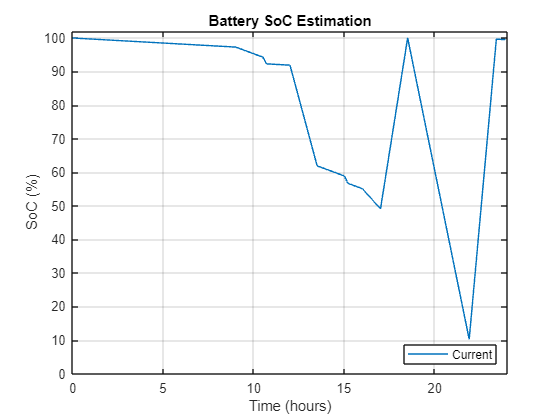

%% Plot Figure
figure;
plot(tt,soc_t*100)
xlabel('Time (hours)');
ylabel('SoC (%)');
title('Battery SoC Estimation');
xlim([0 tf])
ylim([0 102])
legend('Current','Location','southeast');
grid on;

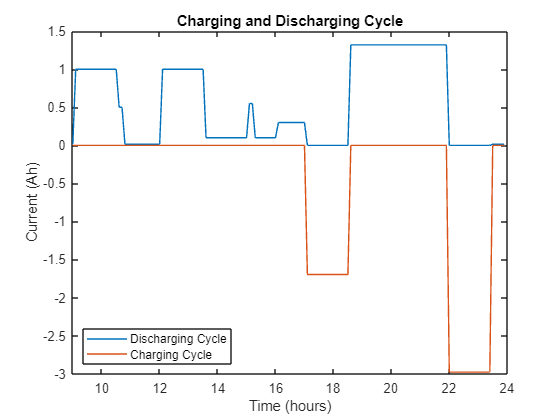

% Discharging and Charging Cycle 
figure;
plot(tt,i_d, tt, i_c);
xlim([9 tf])
xlabel('Time (hours)');
ylabel('Current (Ah)');
title('Charging and Discharging Cycle');
legend('Discharging Cycle','Charging Cycle','Location','southwest');

#### **M Script Code**

### **OCV Vs SoC**

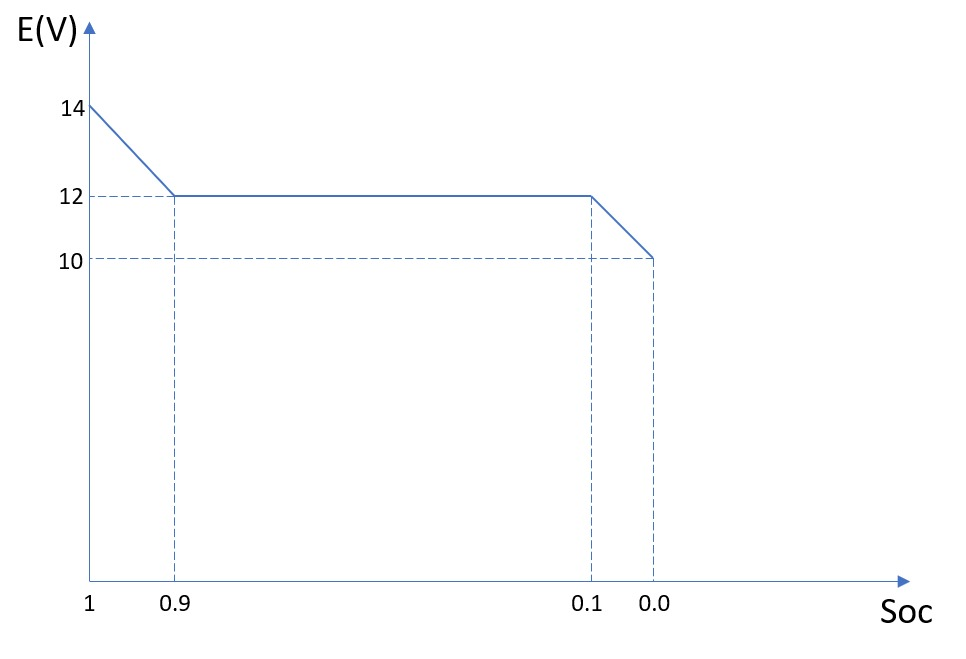

#### **Questions**

- Determine the linear equations of the characterisitics and their operating range.

- Write a matlab script, the corresponding function of $E=f\left(\textrm{SoC}\right)$

- The battery has an internal resistance of $r=0\ldotp 05\;\Omega \;$Write another function $V=f\left(I,\textrm{SoC}\right)$ that outputs the terminal voltage $V=E-r\;I$and uses previous function

- (Replicate the figure) Plot the graph of E(V) against SoC.** Additional:** Use Sigmoid function to transform the linear to smooth curve.

 **Segment A**

@ soc = 1 to 0.9; ocv drops from 14v to 12v


$$\begin{array}{l}
\textrm{Equation}\;\textrm{of}\;\textrm{line}:y=\textrm{ax}+b\;----------\left(i\right)\\
\textrm{where}\;y=E,x=\textrm{soc}\\
\textrm{slope}\;\left(a\right)=\frac{y_2 -y_1 }{x_2 -x_{1\;} }=\frac{E_{2\;} -E_1 }{{\textrm{soc}}_2 -{\textrm{soc}}_1 }--------\;\left(\textrm{ii}\right)\\
a\;=\frac{12-14}{0\ldotp 9-1}=\frac{-2}{-0\ldotp 1}=20\\
\textrm{Hence},\\
E=20*\textrm{soc}+b---------------\left(\textrm{iii}\right)\\
\left(\textrm{soc},E\right)=\left(1,14\right)\\
\textrm{Substitute}\;\textrm{the}\;\textrm{value}\;\textrm{in}\;\left(\textrm{iii}\right)\\
14=20*1+b\\
14-20=b\\
b=-6-------------------\;\left(\textrm{iv}\right)\\
\textrm{substitute}\;\left(\textrm{iv}\right)\;\textrm{into}\;\left(\textrm{iii}\right)
\end{array}$$


$\textrm{The}\;\textrm{equation}\;\textrm{of}\;\textrm{line}\;\textrm{is}\;E=20*\textrm{soc}-6$; $\textrm{Operating}\;\textrm{range}:0\ldotp 9<\textrm{soc}\le 1$

**Segment B**

@ soc 0.9 to 0.1, The graph is constant.

E = **12V**


$$\textrm{Operating}\;\textrm{range}:0\ldotp 1<\textrm{soc}\le 0\ldotp 9$$


**Segment C**

@ soc = 0.1 to 0, ocv drops from 12v to 10v


$$\begin{array}{l}
\textrm{Equation}\;\textrm{of}\;\textrm{line}:y=\textrm{ax}+b\;----------\left(i\right)\\
\textrm{where}\;y=E,x=\textrm{soc}\\
\textrm{slope}\;\left(a\right)=\frac{y_2 -y_1 }{x_2 -x_{1\;} }=\frac{E_{2\;} -E_1 }{{\textrm{soc}}_2 -{\textrm{soc}}_1 }--------\;\left(\textrm{ii}\right)\\
a\;=\frac{10-12}{0-0\ldotp 1}=\frac{-2}{-0\ldotp 1}=20----------\;\;\;\;\left(\textrm{iii}\right)\\
\textrm{Hence},\\
E=20*\textrm{soc}+b---------------\left(\textrm{iv}\right)\\
\left(\textrm{soc},E\right)=\left(0\ldotp 1,12\right)\\
\textrm{Substitute}\;\textrm{the}\;\textrm{value}\;\textrm{in}\;\left(\textrm{iv}\right)\\
12=20*0\ldotp 1+b\\
12-2=b\\
b=10\;\;-------------------\;\left(v\right)\\
\textrm{substitute}\;\left(v\right)\;\textrm{into}\;\left(\textrm{iv}\right)
\end{array}$$


$\textrm{The}\;\textrm{equation}\;\textrm{of}\;\textrm{line}\;\textrm{is}\;E=20*\textrm{soc}+10$; $\textrm{Operating}\;\textrm{range}:0\le \textrm{soc}\le 0\ldotp 1$


$$E=f\left(\textrm{Soc}\right)$$



$$V=f\left(I,\textrm{SoC}\right)$$


Sigmoid function


$$\sigma =\frac{1}{1-e^{-x} }$$



$$\textrm{ocv}=10+2*\sigma \;\left(\frac{\textrm{soc}-0\ldotp 1}{\beta \;}\right)+2*\sigma \;\left(\frac{\textrm{soc}-0\ldotp 9}{\alpha }\right)$$


- The equation provides a smooth, continuous transition between these voltage levels without abrupt jumps, 

- Which is especially useful in simulations where  smooth behavior are desired.

- The base value (10V)  sets the minimum voltage. This means that at very low soc values, the OCV will be near 10 V.

- $2*\sigma \;\left(\frac{\textrm{soc}-0\ldotp 1}{\beta \;}\right)$ adds 2 volts as soc increases past 0.1. The parameter β controls how gradual or sharp this transition.

- $2*\sigma \;\left(\frac{\textrm{soc}-0\ldotp 9}{\alpha }\right)$ adds another 2 V as soc increases past 0.9. The parameter α\alphaα similarly controls the steepness of this transition.

#### Plotting M Script

#### Figures

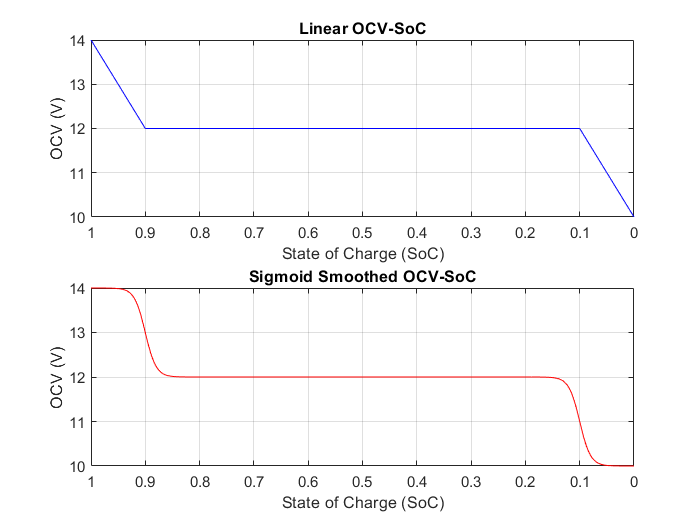

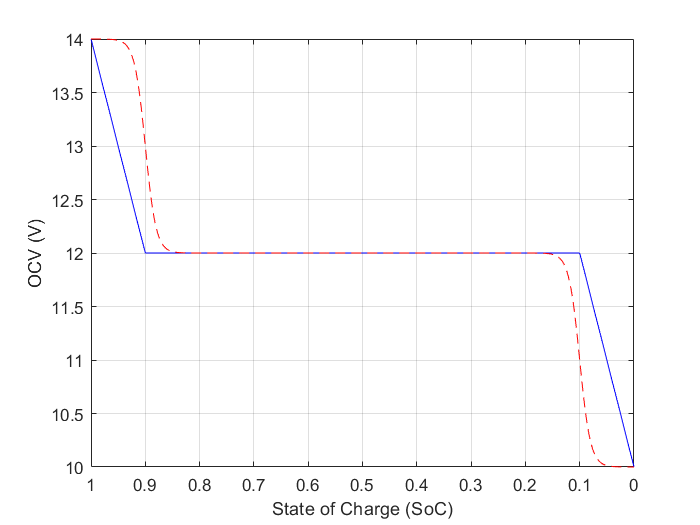

#### Key Takeways

- How to reverse a graph (source: [https://www.mathworks.com/matlabcentral/answers/22321-plotting-and-reversing-axis-direction](https://www.mathworks.com/matlabcentral/answers/22321-plotting-and-reversing-axis-direction))

- Sigmoid function (source: [https://www.geeksforgeeks.org/derivative-of-the-sigmoid-function/](https://www.geeksforgeeks.org/derivative-of-the-sigmoid-function/))

- Matlab Anonymous function (Source: [https://www.mathworks.com/help/matlab/matlab_prog/anonymous-functions.html](https://www.mathworks.com/help/matlab/matlab_prog/anonymous-functions.html))